clear all; close all; clc; clear livescript;

## From class exercises of week 2

% Solve the system of ODE below using the ODE Matlab solver and the symbolic Math toolbox,

% We first solve this numerically with ode23
t = [0 .5];
s0 = [1 2 3];
[t,s] = ode23(@myfunction, t, s0, []);
plot(t,s,'-x')
legend x(t) y(t) z(t)
interp1(s(:,3) , t, 15) % Find t where z(t) is 15

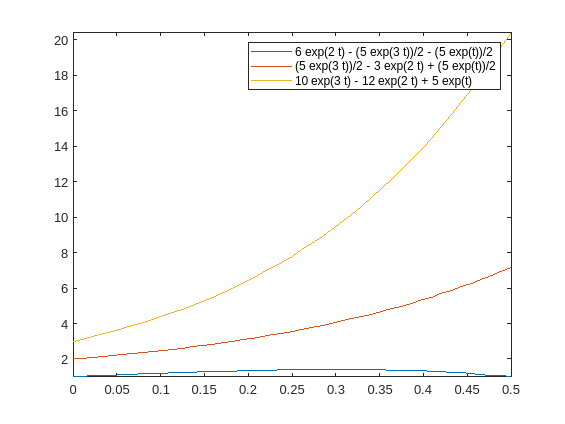

% We then solve this analytically
clear all; clc; close all;

s0 = [1 2 3];

syms x(t) y(t) z(t);

eqns = [
    diff(x, t) == x + 2*y - z
    diff(y, t) == x + z
    diff(z, t) == 4 * x - 4 * y + 5 * z
];
conds = [
    x(0) == 1
    y(0) == 2
    z(0) == 3
];
S = dsolve(eqns, conds, []);

% "hold on;" is necessary to keep all fplot lines in the same image
fplot(S.x, [0 .5]); hold on;
fplot(S.y, [0 .5]); hold on;
fplot(S.z, [0 .5]);
legend;

function ds = myfunction(t, s0)
    x = s0(1);
    y = s0(2);
    z = s0(3);
    dX = x + 2 * y - z;
    dY = x + z;
    dZ = 4 * x - 4 * y + 5 * z;
    ds = [dX; dY; dZ];
end